%%%% ODE, and Optimization


%%% second order ODE 

% % % y'' = 0.5*t*y;
% % % 
% % % y1' = y2;
% % % y2' = 0.5*t*y1;

tspan = [0:0.01:2];

y0 = [0,0.1];

[t,y] = ode45(@(t,y)secondODE(t,y),tspan,y0)

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y =          0    0.1000
    0.0010    0.1000
    0.0020    0.1000
    0.0030    0.1000
    0.0040    0.1000
    0.0050    0.1000
    0.0060    0.1000
    0.0070    0.1000
    0.0080    0.1000
    0.0090    0.1000


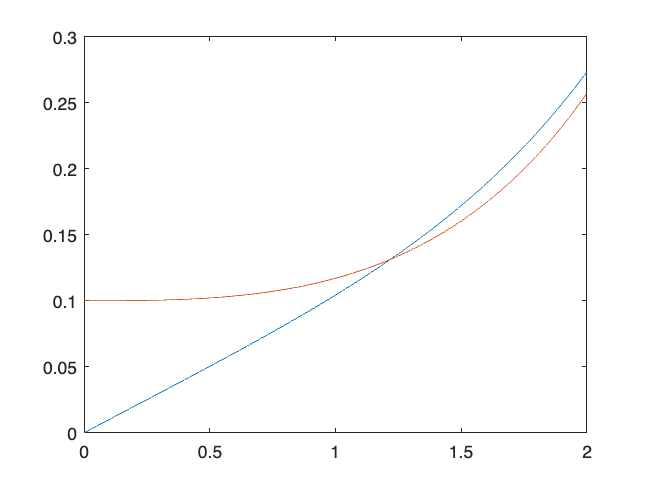


plot(t,y(:,1),t,y(:,2))



y0 = [1 -2];

[t6,y6] = ode45(@secODE,tspan,y0)

t6 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y6 =     1.0000   -2.0000
    0.9798   -2.0499
    0.9590   -2.0996
    0.9378   -2.1490
    0.9160   -2.1982
    0.8938   -2.2471
    0.8711   -2.2958
    0.8479   -2.3441
    0.8242   -2.3921
    0.8000   -2.4398


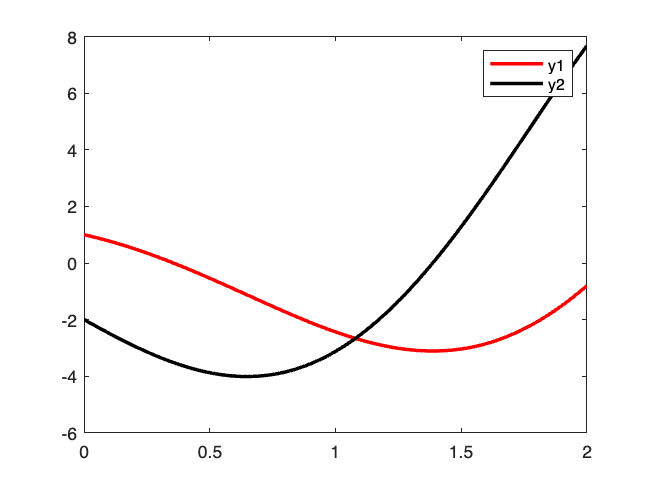

figure
plot(t6,y6(:,1),'-r',t6,y6(:,2),'-k','LineWidth',2)
legend('y1','y2')




%%%% third order ODE y''' = y'' + 3y' + 4y +5;

[t7,y7] = ode45(@thirdode,tspan,[0 0 0])

t7 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


y7 =          0         0         0
    0.0000    0.0003    0.0503
    0.0000    0.0010    0.1010
    0.0000    0.0023    0.1523
    0.0001    0.0041    0.2042
    0.0001    0.0064    0.2567
    0.0002    0.0092    0.3098
    0.0003    0.0126    0.3635
    0.0004    0.0165    0.4178
    0.0006    0.0209    0.4728


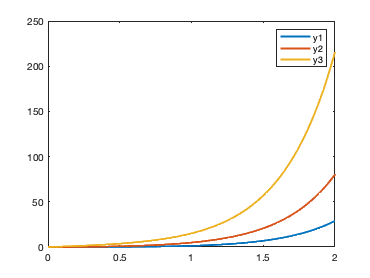

figure
for i = 1:3
    plot(t7,y7(:,i),'LineWidth',2)
    hold on
end
hold off
legend('y1','y2','y3')

function dy = thirdode(t,y)
            dy = zeros(3,1);
            dy(1) = y(2);
            dy(2) = y(3);
            dy(3) = y(3) + 3*y(2) + 4*y(1) + 5;
end

function dydt = secondODE(t,y)
    dydt = zeros(2,1);
    dydt(1) = y(2);
    dydt(2) = 0.5*t*y(1);
end

function dydt = secODE(t,y)
    dydt = zeros(2,1);
    dydt(1) = y(2);
    dydt(2) = t+y(2)-3*y(1);
end
